clear all; close all; format compact; clc;

Loading data

% Get a list of all text files in the folder
path='C:\Users\qdmofa\OneDrive - TUNI.fi\Fincone II-adjunct\Asli\FINCONE II - Analytical tools\Codes\Recompressive CRS\in';
files = dir(path);

% Initialize variables to store the largest and smallest file names and sizes
largest_file = '';
largest_size = 0;

% Loop through the files
for k = 1:length(files)
    % Get the file name and size
    file_name = files(k).name;
    file_size = files(k).bytes;

    % Compare the file size with the current largest and smallest sizes
    if file_size > largest_size
        % Update the largest file name and size
        largest_file = file_name;
        largest_size = file_size;
    end
end

% Load the largest file as a table named "in" with tab delimiter and comma decimal separator
in = readtable(fullfile(path, largest_file), 'Delimiter', '\t', 'DecimalSeparator', ','); %, ...

%     'VariableNames', {'init. height (mm)', 'initial area (cm2)','mass (gr)','time (sec)','step','force measurements (V/V)','displacement (mm)', 'pore water pressure (kPa)', 'init. vertical pressure (kPa)', 'force factor', 'force measurement (kg)','stiffness (mm/kg)','strain rate (mm/min)','displacement per step (mm)','step displacement (mm)','compensated displacement (mm)','stepping speed (step/min)','step interval (ms)','axial compression (%)','vertical total stress (kPa)','vertical effective stress (kPa)','compression module (MPa)','coeff. of consolidation (m2/a)','hydraulic conductivity (m/s^2)'});

% Sort the files by their size in ascending order and get the sorted indices
[~, sorted_indices] = sort([files.bytes]);

% Get the index of the third smallest file
third_smallest_index = sorted_indices(3);

% Get the file name and size of the third smallest file
third_smallest_file = files(third_smallest_index).name;
third_smallest_size = files(third_smallest_index).bytes;

% Create an import options object for the third smallest file that can detect the decimal separator
opts = detectImportOptions(fullfile(path, third_smallest_file), 'Delimiter', '\t');

% Load the third smallest file as a table named "info" with tab delimiter and detected decimal separator
info = readtable(fullfile(path, third_smallest_file), opts);

Input values (GUI)

showGUI = false; % Change this to false if you want to use the default values

% Define the prompt, title, size, and default value for each edit field
prompt = {'Dry mass of specimen, M_d:', 'Initial moist mass of specimen, M_t0:', 'Specific gravity of solids, G_S:', ...
    'Density of water at 20 Celsius, ro_w:', 'Unit weight of water, gamma_w:', ...
    'Loading-Unloading stress levels:'};
dlgtitle = 'User Information';
fieldsize = [1 40; 1 40; 1 40; 1 40; 1 40; 1 40];
definput = {'29', '41.14', '2.67', '0.99821', '9.7891', '[27 4;295 54;442 80;600 0]'};

% Create the dialog box and get the user input if showGUI is true
if showGUI
    in_lab = inputdlg(prompt, dlgtitle, fieldsize, definput);
else
    % Use the default values if showGUI is false
    in_lab = definput;
end

% Check if the user pressed the cancel button or closed the dialog box
if isempty(in_lab)
    disp('No input entered.')
else
    % Display the input values in the command window
    disp(['M_d: ', in_lab{1}])
    disp(['M_t0: ', in_lab{2}])
    disp(['G_S: ', in_lab{3}])
    disp(['ro_w: ', in_lab{4}])
    disp(['gamma_w: ', in_lab{5}])
    disp(['unloading/load stresses: ', in_lab{6}])
end

M_d: 29


M_t0: 41.14


G_S: 2.67


ro_w: 0.99821


gamma_w: 9.7891


unloading/load stresses: [27 4;295 54;442 80;600 0]



UnloadLoad_stress = str2num(cell2mat(in_lab(6)));
in_lab = str2double(in_lab(1:5));

% When the GUI do not pop up, the results are saved i na horizontal array.
% So, I change it always to be a vertical one:
% Check the dimensions of A using the size function
[m,n] = size(in_lab);

% If A is horizontal, transpose it to make it vertical
if m == 1
    in_lab = in_lab.';
end
Md = in_lab(1,1);
Mt0 = in_lab(2,1);
Gs = in_lab(3,1);
ro_w = in_lab(4,1);
gamma_w = in_lab(5,1);

% input values readable from the in table:
H0 = in.Alkukorkeus_mm_(1,1) * 0.1;
A = in.Alkupinta_ala_cm2_(1,1);
compensated_displacement = in.KompensoituSiirtym__mm_;
strain_rate = in.Nousunopeus_mm_min_;

Denoising & downsizing

time = in.Aika_s_;
stress_eff = in.TehokasPystyj_nnitys_kPa_;
stress_tot = in.Pystyj_nnitys_kPa_;
pressure_pore = in.Huokosvedenpaine_kPa_;
strain = in.SuhteellinenKokoonpuristuma___;
% Find the local extrema 
[maxima, maxima_indices] = findpeaks(strain);
[minima, minima_indices] = findpeaks(-strain);
extrm_idx = [maxima_indices;minima_indices];

% Denoise the signal using the default settings
stress_eff_den = wdenoise(stress_eff,9,DenoisingMethod="UniversalThreshold");
strain_den = wdenoise(strain,9,DenoisingMethod="UniversalThreshold");

% Downsizing the signals
[stress_eff_den_downsized, strain_den_downsized, ind_downsizing] = fnc_downsize_stress_strain(stress_eff_den, strain_den, 200);


% plot strain vs. log(stress)
x = stress_eff;
y = strain;
x2 = stress_eff_den;
y2 = strain_den;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([y;y2]); % the distance of annotations from y=0 is a fraction of ylim_max!
for i = 1 : numel(UnloadLoad_stress)
    x3(i,:) = [UnloadLoad_stress(i),UnloadLoad_stress(i)];
    y3(i,:) = [axLim_factor*min([y;y2]),axLim_factor*max([y;y2])];
end
f = figure ('Name','Noisy vs. denoised log(stress)-strain','Position',[100 100 800 600])

f =   Figure (1: Noisy vs. denoised log(stress)-strain) with properties:

      Number: 1
        Name: 'Noisy vs. denoised log(stress)-strain'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 800 600]
       Units: 'pixels'

  Show all properties

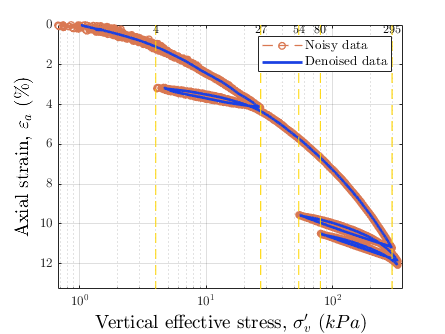

set(f,'defaulttextinterpreter','latex');
% Plot the noisy data
semilogx(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
% Plot the denoised data
semilogx(x2,y2,'-','LineWidth',2,'MarkerSize',10,'Color',[0.1 0.25 0.89])
for i = 1 : numel(UnloadLoad_stress)
    semilogx(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Vertical effective stress, $\sigma^\prime_v$ ($kPa$)','FontSize',14,'Color','k','Interpreter','latex')
ylabel('Axial strain, $\varepsilon_a$ ($\%$)','FontSize',14,'Color','k','Interpreter','latex')
legend('Noisy data','Denoised data','FontSize',10,'Location','northeast','Interpreter','latex')
xlim([min(x) axLim_factor*max(x)])
ylim([min([y;y2]) axLim_factor*max([y;y2])])
set (gca, 'YDir','reverse')
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on


% plot strain vs. stress
f = figure ('Name','Noisy vs. denoised stress-strain','Position',[100 100 800 600])

f =   Figure (2: Noisy vs. denoised stress-strain) with properties:

      Number: 2
        Name: 'Noisy vs. denoised stress-strain'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 800 600]
       Units: 'pixels'

  Show all properties

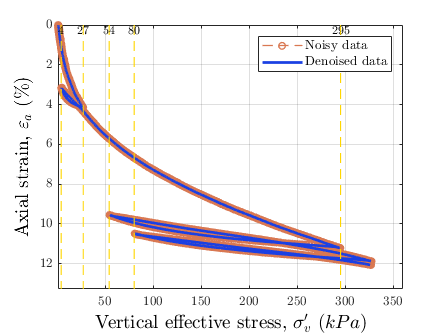

text_loc = 0.02 * axLim_factor*max([y;y2]); % the distance of annotations from y=0 is a fraction of ylim_max!
set(f,'defaulttextinterpreter','latex');
% Plot the noisy data
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
% Plot the denoised data
plot(x2,y2,'-','LineWidth',2,'MarkerSize',10,'Color',[0.1 0.25 0.89])
for i = 1 : numel(UnloadLoad_stress)
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), 0.3, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Vertical effective stress, $\sigma^\prime_v$ ($kPa$)','FontSize',14,'Color','k','Interpreter','latex')
ylabel('Axial strain, $\varepsilon_a$ ($\%$)','FontSize',14,'Color','k','Interpreter','latex')
legend('Noisy data','Denoised data','FontSize',10,'Location','northeast','Interpreter','latex')
xlim([min(x) axLim_factor*max(x)])
ylim([min([y;y2]) axLim_factor*max([y;y2])])
set (gca, 'YDir','reverse')
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on


% plot downsized strain vs. log(stress)
x = stress_eff;
y = strain;
x2 = stress_eff_den_downsized;
y2 = strain_den_downsized;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y);max(y2)]); % the distance of annotations from y=0 is a fraction of ylim_max!
for i = 1 : numel(UnloadLoad_stress)
    x3(i,:) = [UnloadLoad_stress(i),UnloadLoad_stress(i)];
    y3(i,:) = [axLim_factor*min([min(y);min(y2)]), axLim_factor*max([max(y);max(y2)])];
end

f = figure ('Name','Noisy vs. denoised log(stress)-strain','Position',[100 100 800 600])

f =   Figure (3: Noisy vs. denoised log(stress)-strain) with properties:

      Number: 3
        Name: 'Noisy vs. denoised log(stress)-strain'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 800 600]
       Units: 'pixels'

  Show all properties

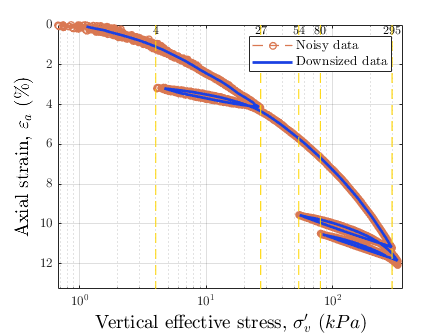

set(f,'defaulttextinterpreter','latex');
% Plot the noisy data
semilogx(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
% Plot the denoised data
semilogx(x2,y2,'-','LineWidth',2,'MarkerSize',10,'Color',[0.1 0.25 0.89])
for i = 1 : numel(UnloadLoad_stress)
    semilogx(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), 0.3, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Vertical effective stress, $\sigma^\prime_v$ ($kPa$)','FontSize',14,'Color','k','Interpreter','latex')
ylabel('Axial strain, $\varepsilon_a$ ($\%$)','FontSize',14,'Color','k','Interpreter','latex')
legend('Noisy data','Downsized data','FontSize',10,'Location','northeast','Interpreter','latex')
xlim([min(x) axLim_factor*max(x)])
ylim([min([min(y);min(y2)]) axLim_factor*max([max(y);max(y2)])])
set (gca, 'YDir','reverse')
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on


% plot downsized strain vs. stress
x = stress_eff;
y = strain;
x2 = stress_eff_den_downsized;
y2 = strain_den_downsized;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y);max(y2)]); % the distance of annotations from y=0 is a fraction of ylim_max!
for i = 1 : numel(UnloadLoad_stress)
    x3(i,:) = [UnloadLoad_stress(i),UnloadLoad_stress(i)];
    y3(i,:) = [axLim_factor*min([min(y);min(y2)]),axLim_factor*max([max(y);max(y2)])];
end

f = figure ('Name','Noisy vs. denoised stress-strain','Position',[100 100 800 600])

f =   Figure (4: Noisy vs. denoised stress-strain) with properties:

      Number: 4
        Name: 'Noisy vs. denoised stress-strain'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 800 600]
       Units: 'pixels'

  Show all properties

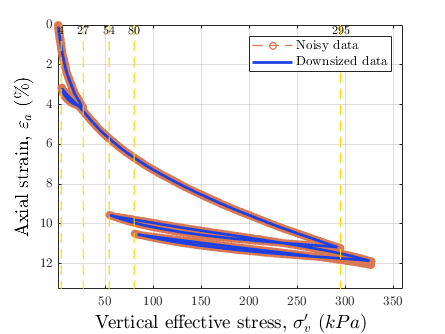

set(f,'defaulttextinterpreter','latex');
% Plot the noisy data
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
% Plot the denoised data
plot(x2,y2,'-','LineWidth',2,'MarkerSize',10,'Color',[0.1 0.25 0.89])
for i = 1 : numel(UnloadLoad_stress)
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), 0.3, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Vertical effective stress, $\sigma^\prime_v$ ($kPa$)','FontSize',14,'Color','k','Interpreter','latex')
ylabel('Axial strain, $\varepsilon_a$ ($\%$)','FontSize',14,'Color','k','Interpreter','latex')
legend('Noisy data','Downsized data','FontSize',10,'Location','northeast','Interpreter','latex')
xlim([min(x) axLim_factor*max(x)])
ylim([min([min(y);min(y2)]) axLim_factor*max([max(y);max(y2)])])
set (gca, 'YDir','reverse')
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on


%%%% u vs. time
x = time(1:end);
y = pressure_pore;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max(max(y)); % the distance of annotations from y=0 is a fraction of ylim_max!
j = 1;
for i = 1 : length(UnloadLoad_stress)
    UnloadLoad_stress_str(j:j+1,1) = ([UnloadLoad_stress(i,1);UnloadLoad_stress(i,2)])
    j = 2 * i + 1;
end

UnloadLoad_stress_str =     27
     4


UnloadLoad_stress_str =     27
     4
   295
    54


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


for i = 1 : numel(extrm_idx)
    x3(i,:) = [time(extrm_idx(i)),time(extrm_idx(i))];
    y3(i,:) = [axLim_factor*min(y),axLim_factor*max(y)];
end
x3 = sort(x3);
f = figure ('Name','Coefficient of consolidation','Position',[100 100 400 300])

f =   Figure (5: Coefficient of consolidation) with properties:

      Number: 5
        Name: 'Coefficient of consolidation'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

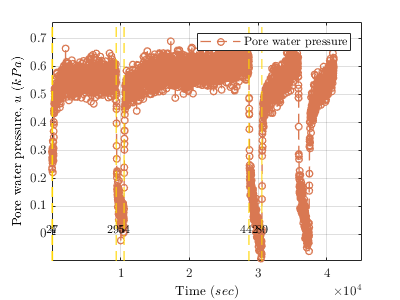

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress)-2
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(UnloadLoad_stress_str(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Time ($sec$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Pore water pressure, $u$ ($kPa$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Pore water pressure','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min(y) axLim_factor*max(y)])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on

% It is proven that the downsized matrix looks similar to the original
% denoised on. So, I will repeat the computations to the required level, to
% use the downsized vectors as the stress and strain vectors.

Interpretation

w0 = ((Mt0 - Md) / Md) * 100;
ro_d = Md / (H0 * A);
Vs = Md / (Gs * ro_w);
Hs = Vs / A;
e0 = (H0 - Hs) / Hs;
S0 = (Gs * w0) / e0;
dH = -1 * diff(compensated_displacement);
Hn = H0 - dH;
en = (Hn - Hs) / Hs;
eps_an = ((H0 - Hn) / H0) * 100;
du = diff(pressure_pore);
kn = (strain_rate(2:end) .* Hn * H0 * gamma_w) ./ ((2 * du) * 10000);
[kn_clean, k_ind_removed] = rmoutliers(kn,"quartiles","ThresholdFactor",90);
k_ind_removed = find(k_ind_removed);

d_mv(:,1) = eps_an(3:end) - eps_an(1:end-2); % strain difference for m_vn
d_mv(:,2) = stress_eff_den(3:end-1) - stress_eff_den(1:end-3); % stress difference for m_vn
mvn = d_mv(:,1) ./ (d_mv(:,2) * 100);
[mvn_clean, mvn_ind_removed] = rmoutliers(mvn,"quartiles","ThresholdFactor",90);
mvn_ind_removed = find(mvn_ind_removed);

cvn = kn(1:end-2) ./ (mvn .* gamma_w);
[cvn_clean, cvn_ind_removed] = rmoutliers(cvn,"quartiles","ThresholdFactor",90);
cvn_ind_removed = find(cvn_ind_removed);

Plots

%%%% k vs. sigma'_v
x = stress_eff_den(2:end);
x(k_ind_removed) = [];
y = kn_clean;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
for i = 1 : numel(UnloadLoad_stress)
    x3(i,:) = [UnloadLoad_stress(i),UnloadLoad_stress(i)];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
f = figure ('Name','Hydraulic conductivity','Position',[100 100 400 300])

f =   Figure (7: Hydraulic conductivity) with properties:

      Number: 7
        Name: 'Hydraulic conductivity'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

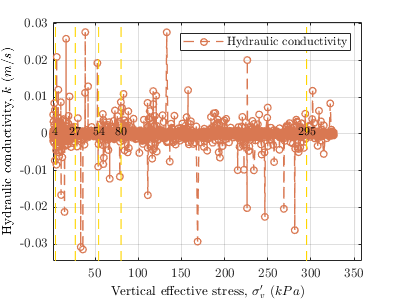

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress)
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Vertical effective stress, $\sigma^\prime_v$ ($kPa$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Hydraulic conductivity, $k$ ($m/s$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Hydraulic conductivity','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on

%%%% k vs. time
x = time(2:end);
x(k_ind_removed) = [];
y = kn_clean;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
j = 1;
for i = 1 : length(UnloadLoad_stress)
    UnloadLoad_stress_str(j:j+1,1) = ([UnloadLoad_stress(i,1);UnloadLoad_stress(i,2)])
    j = 2 * i + 1;
end

UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


for i = 1 : numel(extrm_idx)
    x3(i,:) = [time(extrm_idx(i)),time(extrm_idx(i))];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
x3 = sort(x3);
f = figure ('Name','Hydraulic conductivity','Position',[100 100 400 300])

f =   Figure (8: Hydraulic conductivity) with properties:

      Number: 8
        Name: 'Hydraulic conductivity'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

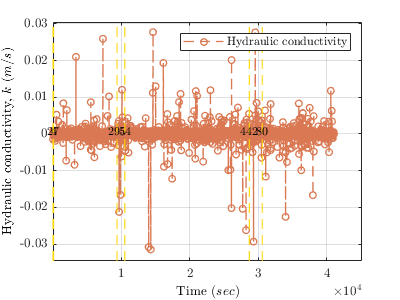

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress) -2
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(UnloadLoad_stress_str(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Time ($sec$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Hydraulic conductivity, $k$ ($m/s$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Hydraulic conductivity','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on


%%%% m_v vs. sigma'_v
x = stress_eff_den(1:end-3);
x(mvn_ind_removed) = [];
y = mvn_clean;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
for i = 1 : numel(UnloadLoad_stress)
    x3(i,:) = [UnloadLoad_stress(i),UnloadLoad_stress(i)];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
f = figure ('Name','Volume compressibility','Position',[100 100 400 300])

f =   Figure (9: Volume compressibility) with properties:

      Number: 9
        Name: 'Volume compressibility'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

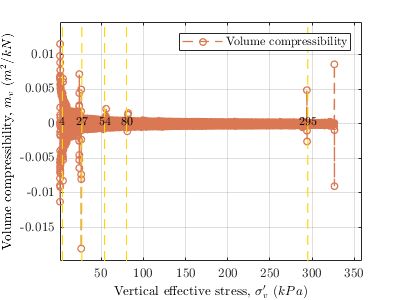

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress)
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Vertical effective stress, $\sigma^\prime_v$ ($kPa$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Volume compressibility, $m_v$ ($m^2/kN$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Volume compressibility','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on

%%%% m_vn vs. time
x = time(1:end-3);
x(mvn_ind_removed) = [];
y = mvn_clean;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
j = 1;
for i = 1 : length(UnloadLoad_stress)
    UnloadLoad_stress_str(j:j+1,1) = ([UnloadLoad_stress(i,1);UnloadLoad_stress(i,2)])
    j = 2 * i + 1;
end

UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


for i = 1 : numel(extrm_idx)
    x3(i,:) = [time(extrm_idx(i)),time(extrm_idx(i))];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
x3 = sort(x3);
f = figure ('Name','Volume compressibility','Position',[100 100 400 300])

f =   Figure (10: Volume compressibility) with properties:

      Number: 10
        Name: 'Volume compressibility'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

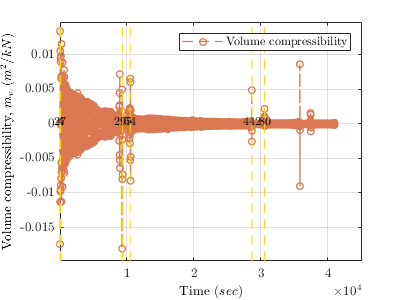

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress) - 2
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(UnloadLoad_stress_str(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Time ($sec$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Volume compressibility, $m_v$ ($m^2/kN$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Volume compressibility','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on


%%%% c_v vs. sigma'_v
x = stress_eff_den(1:end-3);
x(cvn_ind_removed) = [];
y = cvn_clean;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
for i = 1 : numel(UnloadLoad_stress)
    x3(i,:) = [UnloadLoad_stress(i),UnloadLoad_stress(i)];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
f = figure ('Name','Coefficient of consolidation','Position',[100 100 400 300])

f =   Figure (11: Coefficient of consolidation) with properties:

      Number: 11
        Name: 'Coefficient of consolidation'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

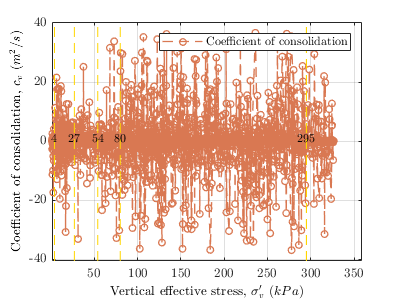

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress)
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Vertical effective stress, $\sigma^\prime_v$ ($kPa$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Coefficient of consolidation, $c_v$ ($m^2/s$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Coefficient of consolidation','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on

%%%% c_v vs. time
x = time(1:end-3);
x(cvn_ind_removed) = [];
y = cvn_clean;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
j = 1;
for i = 1 : length(UnloadLoad_stress)
    UnloadLoad_stress_str(j:j+1,1) = ([UnloadLoad_stress(i,1);UnloadLoad_stress(i,2)])
    j = 2 * i + 1;
end

UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


for i = 1 : numel(extrm_idx)
    x3(i,:) = [time(extrm_idx(i)),time(extrm_idx(i))];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
x3 = sort(x3);
f = figure ('Name','Coefficient of consolidation','Position',[100 100 400 300])

f =   Figure (12: Coefficient of consolidation) with properties:

      Number: 12
        Name: 'Coefficient of consolidation'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

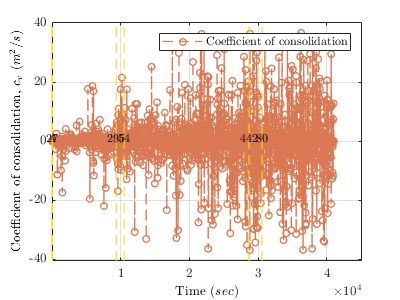

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress) - 2
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(UnloadLoad_stress_str(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Time ($sec$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Coefficient of consolidation, $c_v$ ($m^2/s$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Coefficient of consolidation','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on

Interpretation (denoised)

in_new = in(ind_downsizing,:);

H0_new = in_new.Alkukorkeus_mm_(1,1) * 0.1;
A_new = in_new.Alkupinta_ala_cm2_(1,1);
compensated_displacement_new = in_new.KompensoituSiirtym__mm_;
strain_rate_new = in_new.Nousunopeus_mm_min_;
time_new = in_new.Aika_s_;
stress_eff_new = in_new.TehokasPystyj_nnitys_kPa_;
stress_tot_new = in_new.Pystyj_nnitys_kPa_;
pressure_pore_new = in_new.Huokosvedenpaine_kPa_;
strain_new = in_new.SuhteellinenKokoonpuristuma___;
% Find the local extrema 
[maxima, maxima_indices] = findpeaks(strain_new);
[minima, minima_indices] = findpeaks(-strain_new);
extrm_idx_new = [maxima_indices;minima_indices];

w0 = ((Mt0 - Md) / Md) * 100;
ro_d = Md / (H0_new * A_new);
Vs = Md / (Gs * ro_w);
Hs_new = Vs / A_new;
e0_new = (H0 - Hs_new) / Hs_new;
S0_new = (Gs * w0) / e0_new;
dH_new = -1 * diff(compensated_displacement_new);
Hn_new = H0_new - dH_new;
en_new = (Hn_new - Hs_new) / Hs_new;
eps_an_new = ((H0_new - Hn_new) / H0_new) * 100;
du_new = diff(pressure_pore_new);
kn_new = (strain_rate_new(2:end) .* Hn_new * H0_new * gamma_w) ./ ((2 * du_new) * 10000);
[kn_clean_new, k_ind_removed_new] = rmoutliers(kn_new,"quartiles","ThresholdFactor",90);
k_ind_removed_new = find(k_ind_removed_new);

d_mv_new(:,1) = eps_an_new(3:end) - eps_an_new(1:end-2); % strain difference for m_vn
d_mv_new(:,2) = stress_eff_den_downsized(3:end-1) - stress_eff_den_downsized(1:end-3); % stress difference for m_vn
mvn_new = d_mv_new(:,1) ./ (d_mv_new(:,2) * 100);
[mvn_clean_new, mvn_ind_removed_new] = rmoutliers(mvn_new,"quartiles","ThresholdFactor",90);
mvn_ind_removed_new = find(mvn_ind_removed_new);

cvn_new = kn_new(1:end-2) ./ (mvn_new .* gamma_w);
[cvn_clean_new, cvn_ind_removed_new] = rmoutliers(cvn_new,"quartiles","ThresholdFactor",90);
cvn_ind_removed_new = find(cvn_ind_removed_new);


New plots (after downsizing)

%%%% k vs. sigma'_v
x = stress_eff_den_downsized(2:end);
x(k_ind_removed_new) = [];
y = kn_clean_new;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
for i = 1 : numel(UnloadLoad_stress)
    x3(i,:) = [UnloadLoad_stress(i),UnloadLoad_stress(i)];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
f = figure ('Name','Hydraulic conductivity','Position',[100 100 400 300])

f =   Figure (13: Hydraulic conductivity) with properties:

      Number: 13
        Name: 'Hydraulic conductivity'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

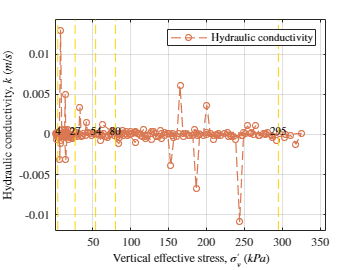

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress)
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Vertical effective stress, $\sigma^\prime_v$ ($kPa$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Hydraulic conductivity, $k$ ($m/s$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Hydraulic conductivity','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on

%%%% k vs. time
x = time_new(2:end);
x(k_ind_removed_new) = [];
y = kn_clean_new;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
j = 1;
for i = 1 : length(UnloadLoad_stress)
    UnloadLoad_stress_str(j:j+1,1) = ([UnloadLoad_stress(i,1);UnloadLoad_stress(i,2)])
    j = 2 * i + 1;
end

UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


for i = 1 : numel(extrm_idx_new)
    x3(i,:) = [time_new(extrm_idx_new(i)),time_new(extrm_idx_new(i))];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
x3 = sort(x3);
f = figure ('Name','Hydraulic conductivity','Position',[100 100 400 300])

f =   Figure (14: Hydraulic conductivity) with properties:

      Number: 14
        Name: 'Hydraulic conductivity'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

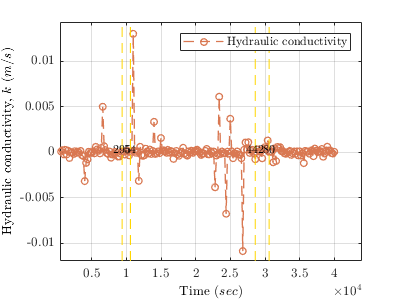

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress) - 2
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(UnloadLoad_stress_str(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Time ($sec$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Hydraulic conductivity, $k$ ($m/s$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Hydraulic conductivity','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on


%%%% m_v vs. sigma'_v
x = stress_eff_den_downsized(1:end-3);
x(mvn_ind_removed_new) = [];
y = mvn_clean_new;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
for i = 1 : numel(UnloadLoad_stress)
    x3(i,:) = [UnloadLoad_stress(i),UnloadLoad_stress(i)];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
f = figure ('Name','Volume compressibility','Position',[100 100 400 300])

f =   Figure (15: Volume compressibility) with properties:

      Number: 15
        Name: 'Volume compressibility'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

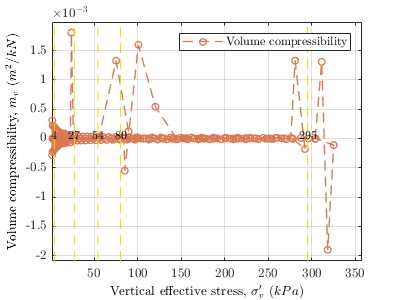

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress)
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Vertical effective stress, $\sigma^\prime_v$ ($kPa$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Volume compressibility, $m_v$ ($m^2/kN$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Volume compressibility','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on

%%%% m_v vs. time
x = time_new(1:end-3);
x(mvn_ind_removed_new) = [];
y = mvn_clean_new;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
j = 1;
for i = 1 : length(UnloadLoad_stress)
    UnloadLoad_stress_str(j:j+1,1) = ([UnloadLoad_stress(i,1);UnloadLoad_stress(i,2)])
    j = 2 * i + 1;
end

UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


for i = 1 : numel(extrm_idx_new)
    x3(i,:) = [time_new(extrm_idx_new(i)),time_new(extrm_idx_new(i))];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
x3 = sort(x3);
f = figure ('Name','Volume compressibility','Position',[100 100 400 300])

f =   Figure (16: Volume compressibility) with properties:

      Number: 16
        Name: 'Volume compressibility'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

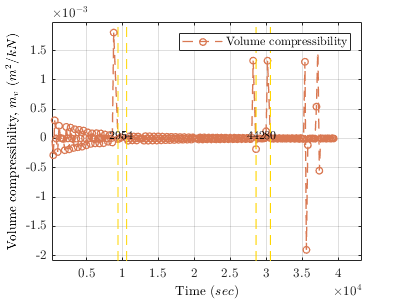

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress) - 2
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(UnloadLoad_stress_str(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Time ($sec$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Volume compressibility, $m_v$ ($m^2/kN$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Volume compressibility','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on


%%%% c_v vs. sigma'_v
x = stress_eff_den_downsized(1:end-3);
x(cvn_ind_removed_new) = [];
y = cvn_clean_new;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
for i = 1 : numel(UnloadLoad_stress)
    x3(i,:) = [UnloadLoad_stress(i),UnloadLoad_stress(i)];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
f = figure ('Name','Coefficient of consolidation','Position',[100 100 400 300])

f =   Figure (17: Coefficient of consolidation) with properties:

      Number: 17
        Name: 'Coefficient of consolidation'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

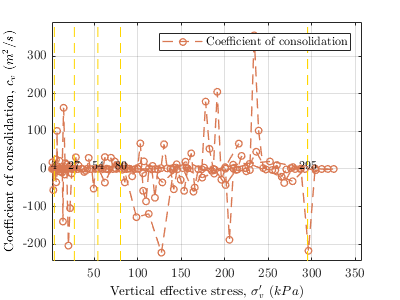

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress)
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Vertical effective stress, $\sigma^\prime_v$ ($kPa$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Coefficient of consolidation, $c_v$ ($m^2/s$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Coefficient of consolidation','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on

%%%% c_v vs. time
x = time_new(1:end-3);
x(cvn_ind_removed_new) = [];
y = cvn_clean_new;
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
j = 1;
for i = 1 : length(UnloadLoad_stress)
    UnloadLoad_stress_str(j:j+1,1) = ([UnloadLoad_stress(i,1);UnloadLoad_stress(i,2)])
    j = 2 * i + 1;
end

UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


for i = 1 : numel(extrm_idx_new)
    x3(i,:) = [time_new(extrm_idx_new(i)),time_new(extrm_idx_new(i))];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
x3 = sort(x3);
f = figure ('Name','Coefficient of consolidation','Position',[100 100 400 300])

f =   Figure (18: Coefficient of consolidation) with properties:

      Number: 18
        Name: 'Coefficient of consolidation'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

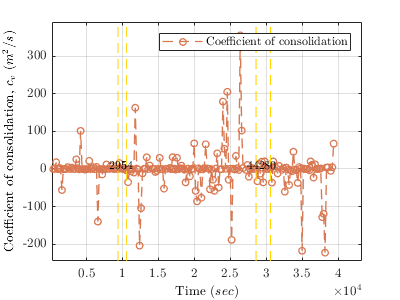

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress) - 2
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
    text(x3(i), text_loc, num2str(UnloadLoad_stress_str(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Time ($sec$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Coefficient of consolidation, $c_v$ ($m^2/s$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Coefficient of consolidation','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on


%%%% u vs. time
x = time_new(1:end);
x(cvn_ind_removed_new) = [];
y = pressure_pore_new;
y(cvn_ind_removed_new) = [];
axLim_factor = 1.1;
text_loc = 0.02 * axLim_factor*max([max(y)]); % the distance of annotations from y=0 is a fraction of ylim_max!
j = 1;
for i = 1 : length(UnloadLoad_stress)
    UnloadLoad_stress_str(j:j+1,1) = ([UnloadLoad_stress(i,1);UnloadLoad_stress(i,2)])
    j = 2 * i + 1;
end

UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


UnloadLoad_stress_str =     27
     4
   295
    54
   442
    80
   600
     0


for i = 1 : numel(extrm_idx_new)
%     if UnloadLoad_stress(i) > 0
%         [~, row] = min(abs(stress_eff_den_downsized' - UnloadLoad_stress(i)), [], 1);
%         result = time_new(row);
%     end
    x3(i,:) = [time_new(extrm_idx_new(i)),time_new(extrm_idx_new(i))];
    y3(i,:) = [axLim_factor*min([y]),axLim_factor*max([y])];
end
x3 = sort(x3);
f = figure ('Name','Pore water pressure','Position',[100 100 400 300])

f =   Figure (19: Pore water pressure) with properties:

      Number: 19
        Name: 'Pore water pressure'
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 400 300]
       Units: 'pixels'

  Show all properties

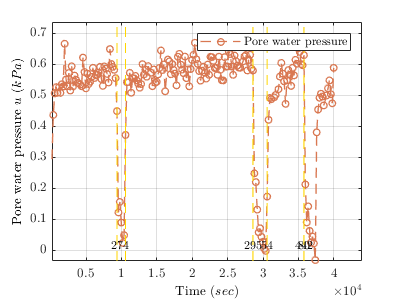

set(f,'defaulttextinterpreter','latex');
plot(x,y,'--o','LineWidth',1,'MarkerSize',5,'Color',[0.85 0.47 0.32])
hold on
for i = 1 : numel(UnloadLoad_stress) - 2
    plot(x3(i,:),y3(i,:),'--','LineWidth',0.8,'Color',[1 0.84 0])
%     text(x3(i), text_loc, num2str(x3(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',8,'Interpreter','latex')
    text(x3(i), text_loc, num2str(UnloadLoad_stress_str(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'on','FontSize',9,'Interpreter','latex')
end
hold off
xlabel('Time ($sec$)','FontSize',10,'Color','k','Interpreter','latex')
ylabel('Pore water pressure $u$ ($kPa$)','FontSize',10,'Color','k','Interpreter','latex')
legend('Pore water pressure','FontSize',9,'Location','northeast','Interpreter','latex')
xlim([axLim_factor*min(x) axLim_factor*max(x)])
ylim([axLim_factor*min([y]) axLim_factor*max([y])])
ax = gca;
set(ax,'TickLabelInterpreter','latex')
grid on